
D_inner                 = 5.538 m
D_outer                 = 5.894 m
Selected inner radius  = 2.769 m
Floor upper surface    = -1.093 m
Cabin width            = 5.461 m
2 x LD3 row width      = 4.013 m
2 x LD3 rows            = 34
Required hold length   = 52.161 m
Cabin length           = 21.257 m
Upper cargo allowance  = 50.627 m
Total fuselage length  = 92.039 m


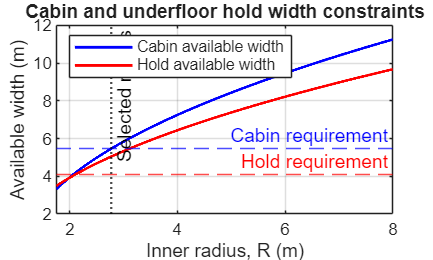

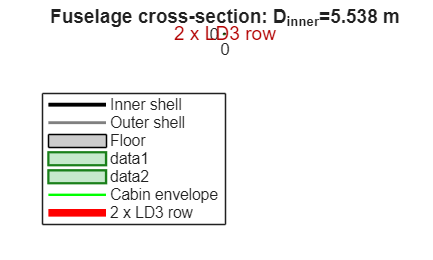

%% Fuselage Cross-Section: Economy Cabin + 2x LD3 Lower Deck

% Uses approximate external LD3-45 dimensions in the x-y cross-section.
% Important: with the supplied floor position, two full-size LD3s do not
% fit completely inside the circular inner fuselage. The script plots them
% in their correct position and marks the out-of-envelope geometry red.

clear; clc; close all;

IN = 0.0254;                            % inch to metre

%% Geometry
P.D_inner = 5.478;                      % Inner diameter [m]
P.D_outer = 5.8336;                     % Outer diameter [m]
P.R_inner = P.D_inner / 2;
P.R_outer = P.D_outer / 2;

P.t_inner_layer = 0.04;                 % Inner lining layer thickness [m]
P.R_mid = P.R_inner + P.t_inner_layer;  % Boundary between wall layers

P.t_floor = 0.05 * P.D_inner;           % Floor thickness [m]
P.yL = -0.8395;                         % Floor upper surface [m]
P.yU = P.yL - P.t_floor;                % Floor lower surface [m]

%% Cabin arrangement parameters
P.clear_w = 2 * IN;                     % Side clearance to inner wall [m]

%% LD3-45 external dimensions, approximately
% Standard nominal dimensions: 60.4 x 61.5 x 64.0 in
% In this cross-section, W is transverse width and H is vertical height.
LD3.W         = 60.4 * IN;              % 1.534 m
LD3.L         = 61.5 * IN;              % Longitudinal length, not used in this view
LD3.H         = 64.0 * IN;              % 1.6256 m
LD3.gap       = 0.05;                   % Gap between containers [m]
LD3.clearance = 0.02;                   % Gap below floor [m]
LD3.chamfer   = 0.30;                   % Bottom corner chamfer [m]

%% Economy class only
ec.name    = 'Economy';
ec.pattern = [3 3 3];
ec.seatW   = 19 * IN;
ec.height  = 39 * IN;
ec.aisle_w = 20 * IN;
ec.color   = [0 0.6 0];                 % Green

%% Plot: single cross-section
figure('Color', 'w', 'Position', [100 100 800 700]);
ax = axes;
hold(ax, 'on'); axis(ax, 'equal'); box(ax, 'on'); grid(ax, 'off');

drawFuselageBase(ax, P);
drawCabinClass(ax, P, ec);
drawCargo(ax, P, LD3);

xlabel(ax, 'Lateral position, x (m)');
ylabel(ax, 'Vertical position, y (m)');
patternStr = strjoin(arrayfun(@num2str, ec.pattern, 'UniformOutput', false), '-');
title(ax, sprintf('%s (%s, %d seats) + 2x LD3 Lower Deck', ...
    ec.name, patternStr, sum(ec.pattern)));

xlim(ax, [-3.2 3.2]);
ylim(ax, [-3.2 3.2]);
legend(ax, 'Location', 'southoutside', 'NumColumns', 3);
hold(ax, 'off');

%% ========================= Local functions =========================

function drawFuselageBase(ax, P)
    th = linspace(0, 2*pi, 500);
    xo = P.R_outer * cos(th); yo = P.R_outer * sin(th);
    xm = P.R_mid   * cos(th); ym = P.R_mid   * sin(th);
    xi = P.R_inner * cos(th); yi = P.R_inner * sin(th);

    patch(ax, [xo fliplr(xm)], [yo fliplr(ym)], [0.35 0.35 0.35], ...
        'EdgeColor', 'none', 'DisplayName', 'Outer skin');
    patch(ax, [xm fliplr(xi)], [ym fliplr(yi)], [0.75 0.75 0.75], ...
        'EdgeColor', 'none', 'DisplayName', 'Inner lining');

    plot(ax, xo, yo, 'k-', 'LineWidth', 2, 'HandleVisibility', 'off');
    plot(ax, xi, yi, 'k-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
    plot(ax, xm, ym, 'k:', 'LineWidth', 0.8, 'HandleVisibility', 'off');

    % Floor polygon clipped to the inner wall.
    xU = sqrt(P.R_inner^2 - P.yU^2);
    xL = sqrt(P.R_inner^2 - P.yL^2);
    patch(ax, [-xU xU xL -xL], [P.yU P.yU P.yL P.yL], [0.8 0.8 0.8], ...
        'EdgeColor', 'none', 'DisplayName', 'Floor');
    plot(ax, [-xU xU], [P.yU P.yU], '-', 'Color', [0.4 0.4 0.4], ...
        'LineWidth', 2, 'HandleVisibility', 'off');
    plot(ax, [-xL xL], [P.yL P.yL], '-', 'Color', [0.4 0.4 0.4], ...
        'LineWidth', 2, 'HandleVisibility', 'off');
    plot(ax, 0, 0, 'k+', 'MarkerSize', 8, 'LineWidth', 1.2, ...
        'HandleVisibility', 'off');
end

function drawCabinClass(ax, P, c)
    nSeats  = sum(c.pattern);
    nAisles = numel(c.pattern) - 1;
    aisle   = c.aisle_w;

    % Seat width is reduced only if the cabin layout exceeds the available
    % width at the lower floor surface.
    wAvail = 2 * sqrt(P.R_inner^2 - P.yU^2) - 2 * P.clear_w;
    seatW  = min(c.seatW, (wAvail - nAisles * aisle) / nSeats);
    if seatW <= 0
        error('Cabin layout does not fit at the floor level.');
    end
    totalW = nSeats * seatW + nAisles * aisle;

    h  = c.height;
    y0 = P.yL;                            % Seats stand on the upper floor
    x  = -totalW / 2;

    for b = 1:numel(c.pattern)
        bw = c.pattern(b) * seatW;
        hv = 'off';
        if b == 1, hv = 'on'; end

        patch(ax, [x x+bw x+bw x], [y0 y0 y0+h y0+h], c.color, ...
            'FaceAlpha', 0.25, 'EdgeColor', c.color, 'LineWidth', 1.5, ...
            'DisplayName', sprintf('%s seat block', c.name), ...
            'HandleVisibility', hv);

        for s = 1:c.pattern(b)-1
            xd = x + s * seatW;
            plot(ax, [xd xd], [y0 y0+h], '-', 'Color', c.color, ...
                'LineWidth', 0.8, 'HandleVisibility', 'off');
        end
        x = x + bw;

        if b < numel(c.pattern)
            patch(ax, [x x+aisle x+aisle x], [y0 y0 y0+h y0+h], ...
                [0.93 0.93 0.93], 'FaceAlpha', 0.6, 'EdgeColor', 'none', ...
                'DisplayName', 'Aisle', 'HandleVisibility', hv);
            text(ax, x + aisle/2, y0 + h + 0.12, 'Aisle', ...
                'HorizontalAlignment', 'center', 'FontSize', 8);
            x = x + aisle;
        end
    end
end

function drawCargo(ax, P, L)
    % Put the tops just below the actual lower face of the floor. Do not use
    % yL here: yL is the cabin-side surface and would make the cargo overlap
    % the floor thickness.
    yTop = P.yU - L.clearance;
    yBot = yTop - L.H;

    hw = L.W / 2;
    c  = min(L.chamfer, hw);
    cx = [-(hw + L.gap/2), hw + L.gap/2];

    allInside = true;
    for k = 1:2
        xc = cx(k);
        px = xc + [-hw, hw, hw, hw-c, -hw+c, -hw];
        py =      [yTop, yTop, yBot+c, yBot, yBot, yBot+c];

        inside = all((px.^2 + py.^2) <= P.R_inner^2 + 1e-10);
        allInside = allInside && inside;

        if inside
            face = [1 0.6 0.1];
            edge = 'k';
        else
            face = [1 0.15 0.05];
            edge = [0.75 0 0];
        end

        hv = 'off';
        if k == 1, hv = 'on'; end
        patch(ax, px, py, face, 'FaceAlpha', 0.8, 'EdgeColor', edge, ...
            'LineWidth', 1.2, 'DisplayName', 'LD3 container', ...
            'HandleVisibility', hv);
        text(ax, xc, (yTop + yBot)/2, 'LD3', 'HorizontalAlignment', 'center', ...
            'FontWeight', 'bold', 'FontSize', 10);
    end

    if allInside
        fprintf('Two LD3 containers fit inside the inner fuselage.\n');
    else
        warning(['Two full-size LD3 containers do not fit inside the circular ', ...
            'inner fuselage with the specified floor position. Red outlines ', ...
            'show the portions outside the pressure shell.\n', ...
            'LD3 top = %.3f m, bottom = %.3f m, height = %.3f m.'], ...
            yTop, yBot, L.H);
    end
end
